clear;clc;

## 读取数据

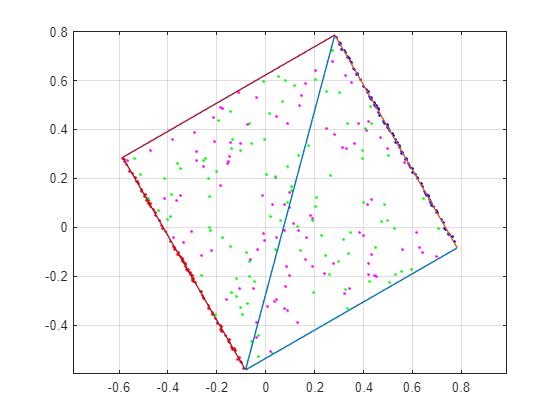

load("PointFangXing.mat")
PAB = [-0.176,-0.06,0.6];
P_bound1 = [-0.142,0.47,0.061];
P_bound2 = [0.57,0.28,0.138];
shenglunum = 6;
phi = pi./3;
phi = pi./2-phi;

PlaneParaIn = [];
[PlaneParaOut,TrianglePoints] = planefit(face3_transformed, ...
    PlaneParaIn,BoundPoint1,BoundPoint2);

figure;
hold on
scatter3(face3_transformed(1, :), face3_transformed(2, :), face3_transformed(3, :), 'r.');
% plot3(TrianglePoints(1,[1:3,1]),TrianglePoints(2,[1:3,1]),TrianglePoints(3,[1:3,1]))
% plot3(TrianglePoints(1,[4:6,4]),TrianglePoints(2,[4:6,4]),TrianglePoints(3,[4:6,4]))


%% 平面2
[PlaneParaOut2,TrianglePoints2] = planefit(face1_transformed, ...
    PlaneParaOut,BoundPoint1,BoundPoint2);

scatter3(face1_transformed(1, :), face1_transformed(2, :), face1_transformed(3, :), 'g.');
% plot3(TrianglePoints2(1,[1:3,1]),TrianglePoints2(2,[1:3,1]),TrianglePoints2(3,[1:3,1]))
% plot3(TrianglePoints2(1,[4:6,4]),TrianglePoints2(2,[4:6,4]),TrianglePoints2(3,[4:6,4]))
% plot3(TrianglePoints2(1,[7:9,7]),TrianglePoints2(2,[7:9,7]),TrianglePoints2(3,[7:9,7]))
% plot3(TrianglePoints2(1,[10:12,10]),TrianglePoints2(2,[10:12,10]),TrianglePoints2(3,[10:12,10]))


%% 平面3
[PlaneParaOut3,TrianglePoints3] = planefit(face4_transformed, ...
    PlaneParaOut2,BoundPoint1,BoundPoint2);

scatter3(face4_transformed(1, :), face4_transformed(2, :), face4_transformed(3, :), 'b.');
% plot3(TrianglePoints3(1,[1:3,1]),TrianglePoints3(2,[1:3,1]),TrianglePoints3(3,[1:3,1]))
% plot3(TrianglePoints3(1,[4:6,4]),TrianglePoints3(2,[4:6,4]),TrianglePoints3(3,[4:6,4]))
% plot3(TrianglePoints3(1,[7:9,7]),TrianglePoints3(2,[7:9,7]),TrianglePoints3(3,[7:9,7]))
% plot3(TrianglePoints3(1,[10:12,10]),TrianglePoints3(2,[10:12,10]),TrianglePoints3(3,[10:12,10]))
% plot3(TrianglePoints3(1,[13:15,13]),TrianglePoints3(2,[13:15,13]),TrianglePoints3(3,[13:15,13]))
% plot3(TrianglePoints3(1,[16:18,16]),TrianglePoints3(2,[16:18,16]),TrianglePoints3(3,[16:18,16]))

%% 平面4
[PlaneParaOut4,TrianglePoints4] = planefit(face2_transformed, ...
    PlaneParaOut3,BoundPoint1,BoundPoint2);

scatter3(face2_transformed(1, :), face2_transformed(2, :), face2_transformed(3, :), 'm.');
plot3(TrianglePoints4(1,[1:3,1]),TrianglePoints4(2,[1:3,1]),TrianglePoints4(3,[1:3,1]))
plot3(TrianglePoints4(1,[4:6,4]),TrianglePoints4(2,[4:6,4]),TrianglePoints4(3,[4:6,4]))
plot3(TrianglePoints4(1,[7:9,7]),TrianglePoints4(2,[7:9,7]),TrianglePoints4(3,[7:9,7]))
plot3(TrianglePoints4(1,[10:12,10]),TrianglePoints4(2,[10:12,10]),TrianglePoints4(3,[10:12,10]))
plot3(TrianglePoints4(1,[13:15,13]),TrianglePoints4(2,[13:15,13]),TrianglePoints4(3,[13:15,13]))
plot3(TrianglePoints4(1,[16:18,16]),TrianglePoints4(2,[16:18,16]),TrianglePoints4(3,[16:18,16]))
plot3(TrianglePoints4(1,[19:21,19]),TrianglePoints4(2,[19:21,19]),TrianglePoints4(3,[19:21,19]))
plot3(TrianglePoints4(1,[22:24,22]),TrianglePoints4(2,[22:24,22]),TrianglePoints4(3,[22:24,22]))

box on
grid on
axis equal

## 矩形拟合

% 取八个点
Pdd = TrianglePoints4(:,[1:3,6,9,16:18])

Pdd =    -0.5850   -0.5848   -0.0829   -0.0826    0.2824    0.7830    0.2826    0.7833
    0.2859    0.2856   -0.5835   -0.5840    0.7864   -0.0843    0.7861   -0.0848
    0.5999   -0.4007    0.5995   -0.4000    0.6012    0.6008   -0.4005   -0.3998


P1 = Pdd(:,1);
P2 = Pdd(:,2);
P3 = Pdd(:,3);
P4 = Pdd(:,4);
P5 = Pdd(:,5);
P6 = Pdd(:,6);
P7 = Pdd(:,7);
P8 = Pdd(:,8);

% 计算轴线
Tao1 = (P3-P1)./norm(P3-P1);
Tao2 = (P4-P2)./norm(P4-P2);
Tao3 = (P6-P5)./norm(P6-P5);
Tao4 = (P8-P7)./norm(P6-P5);
Tao = (Tao1+Tao2+Tao3+Tao4)./4;

% 计算投影点
[xN1,yN1,zN1] = foot_of_perpendicular_from_a_point_to_a_line(P_bound1,P1,P3);
PP1 = [xN1,yN1,zN1];

[xN2,yN2,zN2] = foot_of_perpendicular_from_a_point_to_a_line(P_bound1,P2,P4);
PP2 = [xN2,yN2,zN2];

[xN3,yN3,zN3] = foot_of_perpendicular_from_a_point_to_a_line(P_bound2,P1,P3);
PP3 = [xN3,yN3,zN3];

[xN4,yN4,zN4] = foot_of_perpendicular_from_a_point_to_a_line(P_bound2,P2,P4);
PP4 = [xN4,yN4,zN4];

[xN5,yN5,zN5] = foot_of_perpendicular_from_a_point_to_a_line(P_bound1,P5,P6);
PP5 = [xN5,yN5,zN5];

[xN6,yN6,zN6] = foot_of_perpendicular_from_a_point_to_a_line(P_bound2,P5,P6);
PP6 = [xN6,yN6,zN6];

[xN7,yN7,zN7] = foot_of_perpendicular_from_a_point_to_a_line(P_bound1,P7,P8);
PP7 = [xN7,yN7,zN7];

[xN8,yN8,zN8] = foot_of_perpendicular_from_a_point_to_a_line(P_bound2,P7,P8);
PP8 = [xN8,yN8,zN8];

% 计算进口中心
temp1 = (PP2+PP5)./2;
temp2 = (PP1+PP7)./2;
Pin = (temp1+temp2)./2;

% 计算出口中心
temp3 = (PP3+PP8)./2;
temp4 = (PP4+PP6)./2;
Pout = (temp3+temp4)./2;

% 计算上顶点
RP = (PP1+PP5)./2;
UPP = (PP5+PP7)./2;

% 计算长宽高
b = dist(PP1,PP5');
h = dist(PP1,PP2');
w = dist(PP1,PP3');

% 验证 ok
% scatter3(P_bound1(1),P_bound1(2),P_bound1(3),100,'filled')
% scatter3(P_bound2(1),P_bound2(2),P_bound2(3),100,'filled')
% scatter3(UPP(1),UPP(2),UPP(3),100,'filled')
% scatter3(Pin(1),Pin(2),Pin(3),100,'filled')
% scatter3(PAB(:,1),PAB(:,2),PAB(:,3),220,'filled')
% scatter3(PP1(1),PP1(2),PP1(3),50,'filled')
% scatter3(PP2(1),PP2(2),PP2(3),50,'filled')
% scatter3(PP3(1),PP3(2),PP3(3),50,'filled')
% scatter3(PP4(1),PP4(2),PP4(3),50,'filled')
% scatter3(PP5(1),PP5(2),PP5(3),50,'filled')
% scatter3(PP6(1),PP6(2),PP6(3),50,'filled')
% scatter3(PP7(1),PP7(2),PP7(3),50,'filled')
% scatter3(PP8(1),PP8(2),PP8(3),50,'filled')

## 平移以及计算旋转矩阵

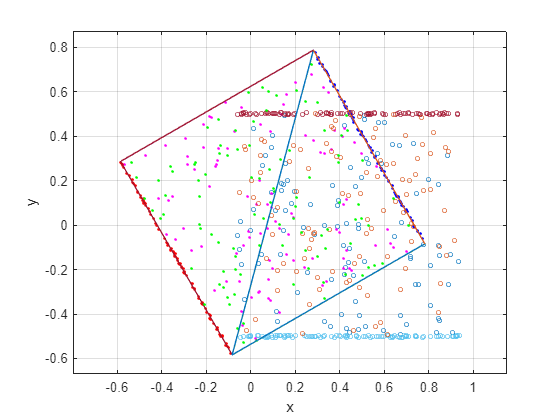

% 记录旋转内容
% 顶点、UPP、Pin、Pout、PAB、Tao
PP = [PP1;PP2;PP3;PP4;PP5;PP6;PP7;PP8];   % 8个顶点

% 平移 Pin
UPPmove = UPP-Pin;
PPmove = PP- repmat(Pin,size(PP,1),1);
Pinmove = Pin-Pin;
Poutmove = Pout-Pin;
PABmove = PAB-Pin;

% 构建旋转矩阵1,pt6转到z轴
theta1 = atan2(norm(cross([0, 0, 1], UPPmove)), dot([0, 0, 1], UPPmove));
v1 = cross([0, 0, 1],UPPmove) / norm(cross([0, 0, 1], UPPmove));
rot1 = myvrrotvec2mat([v1, theta1]);

% Tao旋转rot1
TaoRot1 = Tao'*rot1;

% 构建旋转矩阵2,taorot1转到x轴
theta2 = atan2(norm(cross([1, 0, 0], TaoRot1)), dot([1, 0, 0], TaoRot1));
v2 = cross([1, 0, 0],TaoRot1) / norm(cross([1, 0, 0], TaoRot1));
rot2 = myvrrotvec2mat([v2, theta2]);

% 总的旋转矩阵 ROT
ROT = rot1*rot2;

% 验证
F1move= face1_transformed - repmat(Pin',1,size(face1_transformed,2));
F2move= face2_transformed - repmat(Pin',1,size(face2_transformed,2));
F3move= face3_transformed - repmat(Pin',1,size(face3_transformed,2));
F4move= face4_transformed - repmat(Pin',1,size(face4_transformed,2));


F2rot = F1move'*ROT;
F3rot = F2move'*ROT;
F4rot = F3move'*ROT;
F1rot = F4move'*ROT;

rotupp6 = UPPmove*ROT;
PProt = PPmove*ROT;
PABrot = PABmove*ROT;

% scatter3(Pinmove(1),Pinmove(2),Pinmove(3),50,'filled')
% scatter3(rotupp6(1),rotupp6(2),rotupp6(3),50,'filled')
% scatter3(PProt(:,1),PProt(:,2),PProt(:,3),50,'filled')
% scatter3(PABrot(:,1),PABrot(:,2),PABrot(:,3),220,'filled')

scatter3(F2rot(:,1),F2rot(:,2),F2rot(:,3),10)
scatter3(F3rot(:,1),F3rot(:,2),F3rot(:,3),10)
scatter3(F4rot(:,1),F4rot(:,2),F4rot(:,3),10)
scatter3(F1rot(:,1),F1rot(:,2),F1rot(:,3),10)

xlabel('x')
ylabel('y')

## 计算A点

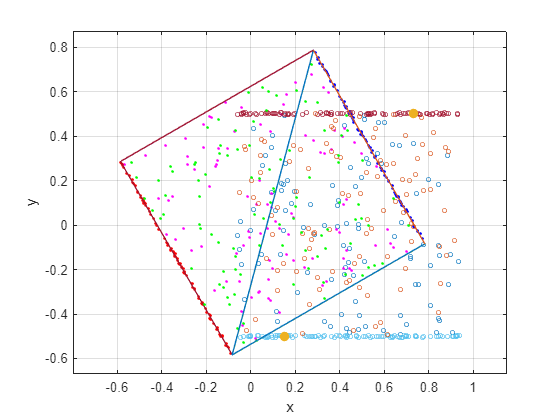

Ti = ShengDaoGaoDu(shenglunum);

% 在PABrot的基础上增量xyz
% x为b*tan(phi)
% y为b
% z为Ti*h
xbase = PABrot(1);
Px = ones(1,shenglunum);
Ax = [b./2*tan(phi).*Px,-b./2*tan(phi).*Px]+xbase;
Ay = [b./2.*Px,-b./2.*Px];
Az = Ti.*h./2;

scatter3(Ax,Ay,Az,50,'filled')

## 计算并偏移

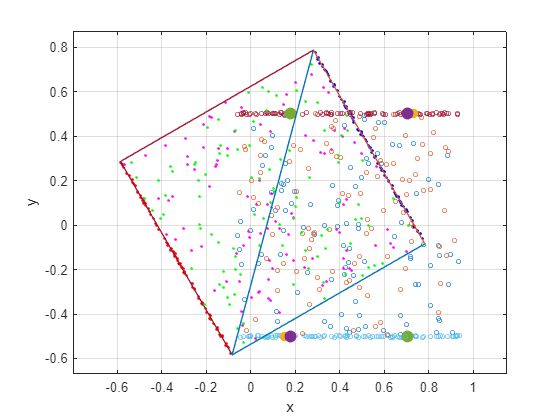

a = 0.015*ones(1,shenglunum);
toff = [-a./tan(phi),a./tan(phi)];
Axoff = Ax + toff;
scatter3(Axoff,Ay,Az,80,'filled')

PointsArot = [Axoff;Ay;Az];
PointsBrot = [Axoff;-Ay;Az];
scatter3(Axoff,-Ay,Az,80,'filled')

## 旋转平移回去

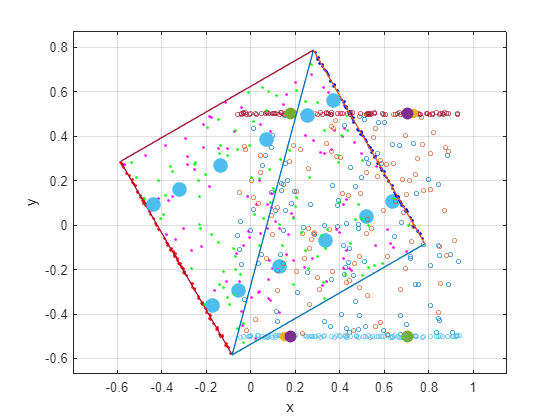

PointsA = PointsArot'*pinv(ROT)+ repmat(Pin,2*shenglunum,1);
PointsB = PointsBrot'*pinv(ROT)+ repmat(Pin,2*shenglunum,1);
PointsA = PointsA';
PointsB = PointsB';


scatter3(PointsA(1,:),PointsA(2,:),PointsA(3,:),120,'filled')